# Hyperfine splitting of the ground state energy levels of alkali-metal atoms and effect of external magnetic field: Breit-Rabi diagram 

Temo Vekua

March 16, 2021

## **Zero external magnetic field case**

    In this Live Script we will use SI international system of units.

    The lowest (ground state) energy electron configuration of alkali-metal atoms (atoms of lithium, sodium, potassium, rubidium, etc.) is characterized by the fully packed inner electron energy shells and one outer (valence) electron in the s-shell (with zero orbital angular momentum $L=0$). In such situation there is no fine-structure splitting of the Coulomb degeneracy of energy levels (fine-structure splitting is due to electron spin-orbit interaction that follows from the relativistic Dirac equation) and total electron angular momentum is entirely accounted by the outer (uncompensated) electron's spin ${\bf J}_e={\bf S}_e$ (bold letters denote vector operators). We remind that electron's spin when measured along any direction can take value either $\hbar/2$ or $-\hbar/2$, with reduced Planck's constant $\hbar$. 

    Hyperfine coupling in hydrogen and alkali-metal atoms between electron's magnetic moment ${\bf \mu}_e=g_e\mu_B {\bf J}_e/\hbar$ (with $g_e$ denoting electron's $g$ factor, $\mu_B=e\hbar /(2m_e)$ - the Bohr magneton, $e$ - charge of a proton, and $m_e$ - electron's mass) and nuclear magnetic moment ${\bf \mu}_n=g_I\mu_B {\bf I}_n/\hbar$ ($g_I$ denoting nuclear $g$ factor and ${\bf I}_n$- the total spin of the nucleus, accounting for both the intrinsic spin angular momentum of the protons and neutrons and their orbital angular momentum within the nucleus) was derived by Fermi [1] (Fermi contact interaction): 

$(1) \quad H_{hf} = A_{hf} {\bf J}_e {\bf  I}_n/\hbar^2=A_{hf} {\bf S I}$,

where we have introduced dimensionless electron and nuclear spin vector operators: ${\bf S}= {\bf S}_e /\hbar$ and ${\bf I}= {\bf I}_n/\hbar$.                                            

In Eq. (1) 

$A_{hf} = -2\mu_0 g_Sg_I \mu^2_B|\psi(0)|^2/3$, 

where $\mu_0=2 \alpha h/(e^2 c)$ is magnetic vacuum permeability (with $\alpha \simeq 1/137$ fine structure constant, $h=2\pi \hbar$ Planck's constant and $c$ speed of light in vacuum), $g_S$ is electron's spin $g$ factor, $g_S=-g_e=2.0023...$ (typically $|g_S/g_I|\sim 10^{4}$), and $$\psi(0)$$ is the outer electron's wavefunction at the position of the nucleus. Except of s-orbital states, all others (p, d, f,...) have nodes at the position of nucleus, thus Fermi contact interaction (1) is important for electrons in s orbitals (however this does not mean that there is no hyperfine coupling for electrons in other than s orbtals). 

    Let's check that $A_{hf}$ has a dimension of energy using symbolic math toolbox  (being a probability density, dimension of $|\psi|^2$ is inverse volume, or, in $3d$ space $metre^{-3}$).

u = symunit; % symbolic variable u carries collection of units, e.g. u.m represents a metre
% with newUnit function we define unit for Bohr magneton 
mu_Bohr=newUnit('mu_Bohr', u.e*u.hbar/u.m_e);     
eqn = u.J == u.mu_0*u.mu_Bohr^2/u.m^3; % u.J carries Joule, dimension of energy in SI
checkUnits(eqn,'Compatible')

ans = logical
   1


    Eq. (1) describes coupling of the magnetic field created by electron (due to its magnetic moment) with the nuclear magnetic moment located at the core of the atom. Electron's wavefunction of heavy atoms are not well known, and in addition, unlike Fermi's approximation, the nuclear magnetic dipole is not point-like. In general, accurate values of $A_{hf}$ is determined from experiments. Hyperfine interaction Eq. (1) plays an important role in electron paramagnetic resonance (EPR) spectroscopy for the compounds containing the unpaired s-shell electrons that are sensitive to their local “micro” environment.

    Let's determine quantum numbers that characterize energy eigenstates of hamiltonian (1). Neither ${\bf S}=(S^x, S^y, S^z)$, nor ${\bf I}=(I^x, I^y, I^z)$ commute with hyperfine hamiltonian given Eq. (1). It is enough to check this for one of the components, say $z$, since there is no preferred direction in the problem without the magnetic field (hamiltonian (1) has $SU(2)$ symmetry). We have,

$[S^z\otimes 1_{2I+1,2I+1}, {\bf S} \otimes {\bf I}]=[S^z\otimes 1_{2I+1,2I+1}, S^x\otimes I^x+S^y \otimes I^y]=i S^y\otimes I^x-i S^x \otimes I^y$,   


$$[I^z, {\bf S  I}]=[I^z, S^xI^x+S^yI^y]=i S^xI^y-i S^yI^x.$$


$1_{(2I+1),(2I+1)$ above stands for a unit matrix of size indicated in the subscript and in the second line of equations we used simplified denotions, not showing a direct product symbol, similar to Eq. (1).  Let's confirm above relations. We will use function `spin` that we provide at the end of the livescript that outputs spin matrices for any spin of integer or half-integer value $1/2,\, 1,\, 3/2,\, 2,...$ and then convert them appropriately to perform symbolic calculation on them. Function `kron` implements tensor (direct) product, e.g. kron(Sx,Ix)= $S^x \otimes I^x$= $S^x \otimes 1_{2I+1,2I+1} \cdot 1_{2S+1,2S+1} \otimes I^x$ (symbol $\cdot$ indicating ordinary, 'inner', matrix multiplication) and eye(X)=diag(ones(X,1)) outputs $1_{X,X}$: X times X unit matrix.

S=1/2;          % value of electron spin
Sx=spin(S,'x'); % spin(Spin_value, component) function is defined at the end of Live Script
Sx=sym(Sx);     % converting double precision numbers stored in matrix Sx to symbolic  
Sy=spin(S,'y');
Sy=sym(Sy);
Sz=spin(S,'z');
Sz=sym(Sz);
I=1;            % here we choose value for nuclear spin 
Ix=spin(I,'x');
Ix=sym(Ix);
Iy=spin(I,'y');
Iy=sym(Iy);
Iz=spin(I,'z');
Iz=sym(Iz);
syms A_hf       % defining symbolic variable
H_hf=A_hf*(kron(Sx,Ix)+kron(Sy,Iy)+kron(Sz,Iz)); % hyperfine hamiltonian matrix

Let's first check that  $S^x \otimes I^x$= $S^x \otimes 1_{2I+1,2I+1} \cdot 1_{2S+1,2S+1} \otimes I^x$ using `isequal` function from symbolic math toolbox:

isequal(kron(Sx,eye(2*I+1))*kron(eye(2*S+1),Ix),kron(Sx,Ix))

ans = logical
   1


Next, we check that commutator of $S^z$ (or any other component of $\bf S$) and $H_{hf}$ is non-zero and confirm that $[S^z, H_{hf}]=A_{hf}i( S^y  I^x- S^x I^y)$.

commutator=@(x,y) x*y-y*x;  % defining commutator of two matrices
isequal(commutator(kron(Sz,eye(2*I+1)),H_hf), A_hf*1i*(kron(Sy,Ix)-kron(Sx,Iy))) 

ans = logical
   1


Similarly we confirm that $[I^z, H_{hf}]=iA_{hf}(S^xI^y-iS^yI^x)$.

isequal(commutator(kron(eye(2*S+1),Iz),H_hf),A_hf*1i*(kron(Sx,Iy)-kron(Sy,Ix)))

ans = logical
   1


    In the absence of the hyperfine interaction (1), both electron ($\bf S$) and nuclear spin vectors ($\bf I$) are conserved quantities and system enjoyes $SU(2)\otimes SU(2)$ symmetry (separate independent rotations of electron and nuclear spins). In the presence of the hyperfine coupling, it is the sum of the nuclear and electron spin vectors ${\bf F}={\bf I}+{\bf S}$ (total spin of the atom) that becomes a conserved quantity and only the diagonal $SU(2)$ symmetry remains (simultaneous rotations of nuclear and electron spins). This is very much similar to the situation when total electron angular momentum ${\bf J}= {\bf L}+{\bf S}$ becomes conserved vector in the presence of spin-orbit interaction $\sim \bf LS$, giving rise to fine structure splitting of electron levels in Dirac theory. To classify eigenstates of the hyperfine hamiltonian (1) one can use quantum numbers corresponding to ${\bf F}^2$ and $F^Z=I^Z+S^Z$ operators. We denote them as $F(F+1)$  and  $m_F=m_S+m_I$ respectively, where $m_S=\pm 1/2$ and $m_I=(-I, -I+1,...I)$. Indeed we have:

 $[F^z, {\bf S  I}]=iS^yI^x-iS^xI^y+iS^xI^y-iS^yI^x=0$. 

Let's confirm this. Simulations remind us true meaning beyond simplified denotions. For example they remind us that the implicit denotion $F^Z=I^Z+S^Z$ truly means $F^z=1_{2x2}\otimes I^z+S^z\otimes 1_{(2I+1)x(2I+1)}$. If we define `>>Fz=Iz+Sz` MATLAB errors out (unless $I=1/2$) since during addition of matrices their dimensions must agree.

Fz=kron(eye(2*S+1),Iz)+kron(Sz,eye(2*I+1));
% if Fz commutes with hamiltonian (1) so will Fx and Fy, as there is no preferred direction
% in the absence of external magnetic field
isequal(commutator(Fz,H_hf),sym(zeros((2*S+1)*(2*I+1))))  

ans = logical
   1


    Hence, eigenstates of hamiltonian (1) can be chosen to be simultaneously eigenstates of both $F^z$ and ${\bf F}^2$ and we will use eigenvalues of $F^z$ and ${\bf F}^2$ to label enegry eignstates of hyperfine hamiltonian (1). 

    For hydrogen and alkali-metal atoms in the ground state there are two possible values that $F$ can take (when $\bf S$ is parallel or antiparallel to $\bf I$): $ F=I\pm 1/2$. Fermi's result tells us that after hyperfine splitting, the lowest energy sector will correspond to $F=I + 1/2$ states if $g_I>0$ (e.g. for: potassium $^{40}$K from [2] $I=4$, $g_I=0.000176490$ and the lowest energy states form $F=9/2$ multiplet, whereas $F=7/2$ multiplet has higher energy) and ground state will correspond to $F=I - 1/2$ if $g_I<0$ (e.g. for: $^{87}$Rb with $I=3/2$, $^{85}$Rb with $I=5/2$, $^{7}$Li with $$I=3/2$$, and $$^{6}$$Li with $I=1
$).

    Next, we calculate the hyperfine splitting between the energy levels with $F=I+1/2$ and $F=I-1/2$. From $({\bf I}+ {\bf S})^2={\bf F}^2$, we have:

$\langle {\bf S} {\bf I}\rangle_F =\langle {\bf F}^2-{\bf S}^2-{\bf I}^2\rangle_F /2=\Big( F(F+1)- S(S+1)- I(I+1) \Big)/2$,                                                                                                  

leading to: $\langle{\bf S} {\bf I}\rangle_{F=I+1/2}- \langle{\bf S} {\bf I}\rangle_{F=I-1/2} =I+1/2$.

Thus, hypeprfine splitting of the ground state energy manifold in alkali-metal atoms in the absence of external magnetic field is:

$
\Delta E_{hf}=A_{hf} \,  \langle{\bf S I}\rangle_{F=I+1/2}- A_{hf}\, \langle{\bf S  I}\rangle_{F=I-1/2}=A_{hf}\, (I+1/2)$.

True value of $A_{hf}$ is determined in experiments spectroscopically from hyperfine splitting formula:


$$(2) \quad A_{hf}=\Delta E_{hf}/(I+1/2).$$


    Without the hyperfine interaction the ground state manifold of an alkali-metal atom is $(2S+1)(2I+1)=2(2I+1)$ times degenerate. Hyperfine interaction (1) splits this degenracy into 2 energy multiplets. These two multiplets have quantum numbers: $F=I+1/2$ (with degeneracy $2I+2$) and $F=I-1/2$ (with degeneracy $2I$).

Let's now calculate eigenenergies of Eq. (1) directly, using `eig` function for $I=1$ case: 

eig(H_hf)

$$ans = \left(\begin{array}{c} -A_{\mathrm{hf}}\\ -A_{\mathrm{hf}}\\ \frac{A_{\mathrm{hf}}}{2}\\ \frac{A_{\mathrm{hf}}}{2}\\ \frac{A_{\mathrm{hf}}}{2}\\ \frac{A_{\mathrm{hf}}}{2} \end{array}\right)$$

We see that for $I=1$ there are two degenerate multiplets of energy, one of them is two-fold degenerate and another - four-fold degenerate and the energy gap between these multiplets is: $\Delta E_{hf}(I=1)=3A_{hf}/2$, consistent with analytical derivation presented above.

## **Exercise**

For hydrogen atom $I=1/2$. Obtain for this case matrix corresponding to ${\bf F}^2$ in the direct product state of electron and proton spins (will be 4x4 matrix) and determine and interpret its eigenvectors and eigenvalues. Represent all eigenvectors of ${\bf F}^2$ as a combination of the direct product of eigenvectors of $S^z$ and $I^z$ operators and then normalize them.

You can use function `eig`: $[F_{eigenvecs},F_{eigenvals}]$`=eig(`${\bf F}^2$`)`, where

${\bf F}^2$$=\left(\begin{array}{cccc}
2 & 0 & 0 & 0\\
0 & 1 & 1 & 0\\
0 & 1 & 1 & 0\\
0 & 0 & 0 & 2
\end{array}\right)$. Note that the matrix corresponding to ${\bf F}^2$ is not diagonal, as opposed to diagonal matrix `diag([3/4,3/4,3/4,3/4]),` corresponding to both ${\bf S}^2$ and ${\bf I}^2$ operators. Middle block of ${\bf F}^2$ is equal to $1_{2,2}+2S^x$. Since eigenvalues of $S^x$ are $\pm 1/2$, one can guess that eigenvalues from the middle block of ${\bf F}^2$ will be 2 and 0.

$F_{eigenvecs}$=$\left(\begin{array}{cccc}
0 & 1 & 0 & 0\\
-1 & 0 & 1 & 0\\
1 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)\ldotp$ Columns of the matrix  $F_{eigenvecs}$ are made from eigenvectors of ${\bf F}^2$ (only two of them are normalized). First column $F_{eigenvecs}(:,1)$ is a (unnormalized) singlet state with $F=0$ and three following columns $F_{eigenvecs}(:,2:4)$ make a triplet state $F=1$ with $m_F=1,0, -1$.

$F_{eigenvals}$=$\left(\begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 2 & 0 & 0\\
0 & 0 & 2 & 0\\
0 & 0 & 0 & 2
\end{array}\right)\ldotp$ Diagonal of this matrix contains eigenvalues of ${\bf F}^2$, that are $F(F+1)$, where $F=I\pm 1/2$ (here eigenvalues of ${\bf F}^2$ are 0 and three 2-s, corresponding to singlet and triplet states respectively).

Note, only two eigenvectors out of four are normalized to unity; these are: $(1,0,0,0)^T$= $(1,0)^T_S \otimes (1,0)^T_I$  (with superscript $T$ indicating transform of a row, hence a column) - the highest weight and $(0,0,0,1)^T$=$(0,1)^T_S \otimes (0,1)^T_I$ - the lowest weight state in $F=I+1/2=1$ subspace. 

Hint: remember derivation of triplet and singlet states for two spin-1/2 vectors. 

State $(0,1,1,0)^T$ is obtained from the highest weight state column $(1,0,0,0)^T$= $(1,0)^T_S \otimes (1,0)^T_I$ by acting with a lowering ladder operator $F^-$. 

Let's calculate matrix corresponding to $F^-=F^x-iF^y$.

S=1/2;
I=1/2;
Sx=sym(spin(S,'x')); 
Sy=sym(spin(S,'y'));
Ix=sym(spin(I,'x'));
Iy=sym(spin(I,'y'));
F_=kron(Sx-1i*Sy,eye(2*I+1))+kron(eye(2*S+1),Ix-1i*Iy)

$$F\_ = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 1 & 0 \end{array}\right)$$

Normalized $m_F=0$ component of the triplet state is


$$(0,1,1,0)^T/\sqrt{2}= (| \uparrow  \rangle_S  \otimes|  \downarrow  \rangle_I  +  |\downarrow  \rangle_S  \otimes|  \uparrow  \rangle_I)/\sqrt{2}.$$
 

syms a 
(kron([1,0]',[0,1]')+kron([0,1]',[1,0]'))/sym(sqrt(2)) %ket vectors are represented as colum

$$ans = \left(\begin{array}{c} 0\\ \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2}\\ 0 \end{array}\right)$$

Normalized singlet state is: $( |\downarrow  \rangle_S  \otimes|  \uparrow  \rangle_I -| \uparrow  \rangle_S  \otimes|  \downarrow  \rangle_I)/\sqrt{2}.$ Up to normalization it coinsides with the first column of $F_{eigenvec}$.

kron([0,1]',[1,0]')-kron([1,0]',[0,1]') % prime transforms row vectors to columns

ans =      0
    -1
     1
     0


Above we used $|\uparrow \rangle_{S/I}=(1,0)^T_{S/I}$ and $|\downarrow \rangle_{S/I}=(0,1)^T_{S/I}$, widely used denotions.

See analytical derivation for any value of $I$ below for details. 

## Coupling alkali-metal atoms to static external magnetic field

    Static external magnetic field $\bf B$ (not too strong to distort electron orbitals) couples to electron and nuclear magnetic moments linearly through Zeeman coupling. Additional contribution to atomic hamiltonian is: $-{\bf \mu}_e {\bf B}-{\bf \mu}_n {\bf B}$ and the shifts and splittings of the lowest energy states of hydrogen and alkali-metal atoms is described by the hyperfine-Zeeman hamiltonian:


$$(3) \quad H_{hf+B}=A_{hf} {\bf S  I} - g_e\mu_B {\bf S  B} - g_I\mu_B {\bf I  B}=A_{hf} {\bf S  I} + g_S\mu_B {\bf S  B} - g_I\mu_B {\bf I  B} .$$


Due to the fact that $|g_S|\gg |g_I|$, magnetic field primarily couples to electron spin. 

    Without loss of generality we will assume that magnetic field is directed along ${\bf e}_z$ axes: ${\bf B}= B {\bf e}_z$. For $B=0$, as we saw above, good quantum numbers are $F$ and $m_F$ (these are called low field quantum numbers). Let's rewrite Eq. (3) in the following way:


$$(4) \quad H_{hf+B}= A_{hf} {\bf S  I}- g_I\mu_B  F^z B +(g_S+g_I)\mu_B S^z  B.$$


Note that $S^z$ commutes with $I^z$ and hence with $F^z$, but $S^z$ does not commute with the hamiltonian (4) due to the first (hyperfine coupling) term, as already shown $[S^z, {\bf S  I}]=iS^yI^x-iS^xI^y$. Consequetly, $S^z$ does not commute with ${\bf F}^2$ (we remind that ${\bf F}^2 =2 {\bf S  I} +{\bf S}^2 +{\bf I}^2$ and $[S^z, {\bf F}^2]=i2S^yI^x-i2S^xI^y$). Hence, nonzero magnetic field $B$ spoils $F$ as a good quantum number (magnetic field breaks $SU(2)$ symmetry), and only one good quantum number remains in the problem: $m_F$ (only $U(1)$ symmetry remains). 

Let's obtain numerically all energy levels of hamiltonian (4) for different values of $B$ using `eig` function and plot them. 

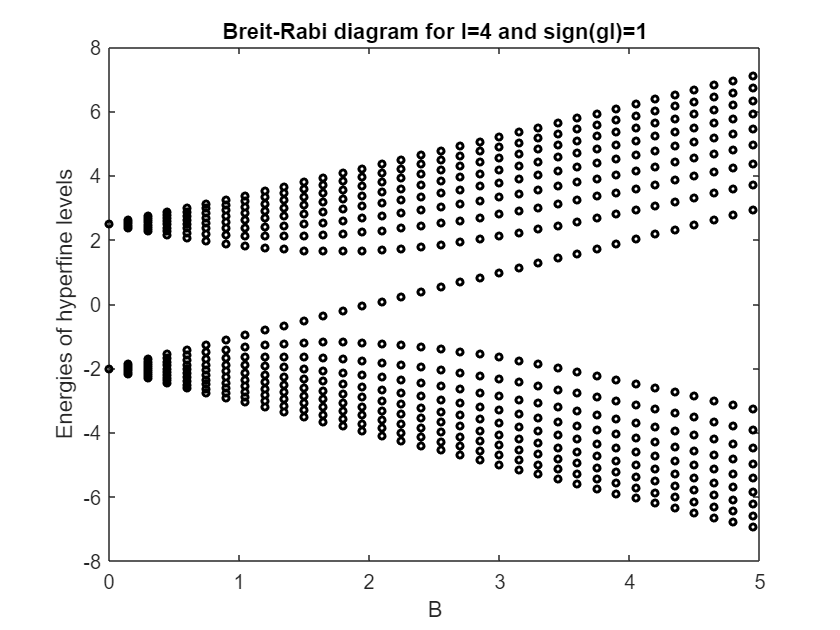

I=4;
Sx=spin(S,'x');       
Sy=spin(S,'y');
Sz=spin(S,'z');
Ix=spin(I,'x');
Iy=spin(I,'y');
Iz=spin(I,'z');

% We will put true values of parameters for fermionic lithium 6 and bosonic rubidium 87 
% atoms at the end of the livescript. Here we put arbitrary numbers and focus on 
% derivation of Breit-Rabi diagram.
muB=1; 
gI=0.001;
gS=2;
A_hf=-sign(gI);

clf;
H_hfB=@(B) (A_hf*(kron(Sx,Ix)+kron(Sy,Iy)+kron(Sz,Iz))-gI*muB*B*kron(eye(2*S+1),Iz)...
          +gS*muB*B*kron(Sz,eye(2*I+1)));  

for B=0:0.15:5
     plot(B,eig(H_hfB(B)),'ko',"MarkerSize",3)
     hold on
end
 xlabel('B')
 ylabel('Energies of hyperfine levels')
 title(sprintf('Breit-Rabi diagram for I=%s and sign(gI)=%g',strtrim(rats(I)),sign(gI)))
 hold off;

Numerical result gives us a hint that the two levels evolve linearly with the magnetic field, hence those two eigenstates of hamiltonian (4) remain to be the same states (they do not change) for any value of $B$ (including $B=0$). Let us confirm this analytically and show that those two states are the ones with with maximal possible value of $|m_F|=I+1/2$. First, we introduce $|F,m_F\rangle$ basis (energy eigenbasis for $B=0$). In this basis hamiltonian (4) is not diagonal, due to the fact that $S^z$ does not commute with the hyperfine hamiltonian Eq. (1). Since $S^z$ commutes with $F^z$, when $S^z$ is applied to $|F,m_F\rangle$ basis state it can not change the value of $m_F$, however $S^z$ does not commute with ${\bf F}^2$, and consequently it can (but not necessarily has to) change the value of $F$ when applied to $|F,m_F\rangle$. Thus, the nonzero overlap between the basis states of $F=I+1/2$ and $F=I-1/2$ subspaces induced by $S^z$ can only be between the states with the same value of $m_F$ (i.e. the nonzero matrix element $\langle I+1/2,m_F| S^z |I-1/2,m'_F\rangle$is only possible if $m'_{F}=m_F$). All terms, except of the last term (containing $\sim BS^z$) of hamiltonian (4) are diagonal in the basis of $|F=I+1/2,m_F\rangle,\,\,\,|F=I-1/2,m_F\rangle$. The diagonal part of the last term of Eq. (4) is given by: 

$(g_I+g_S)\mu_B B \langle I \pm 1/2,m_F| S^z |I\pm 1/2 ,m_F\rangle$,

and the only off-diagonal elements are between the states with the same value of $m_F$ and are given by:


$$(g_I+g_S)\mu_B B \langle I \pm 1/2,m_F| S^z |I\mp 1/2,m_F\rangle.$$


Diagonalization of hamiltonian (4) will lead to the Breit-Rabi diagram, equations describing the dependence of the ground state energy levels of alkali-metal atoms on the strength of the static external magnetic field.

    Let's calculate $\langle F,m_F| S^z |F',m'_F\rangle$ - matrix elements of $S^z$ in the basis of $|F,m_F\rangle,|F',m'_F\rangle$, where $F,F'=I\pm1/2$. We remind action of the lowering ladder operator on the basis states that we will use below:

$J^- | J,m_J\rangle= \sqrt{(J+m_J)(J-m_J+1)}| J,m_J-1\rangle,$ where $J$ can stand for any of the $S,\,  I$, or  $F$.

We construct basis states (normalized to unity) starting from the highest weight states:


$$|F=I+1/2,m_F=I+1/2\rangle=   |1/2,m_S=1/2 \rangle \otimes  |I,m_I=I \rangle= |1/2 \rangle_S  \otimes  |I \rangle_I  \\
 |F=I+1/2,m_F=I+1/2-1\rangle= \alpha F^-|1/2 \rangle_S \otimes |I\rangle_I=  \alpha (I^-+S^-) |1/2 \rangle_S \otimes  | I \rangle_I\\
                        \quad \quad \quad   =\alpha \Big(   |-1/2 \rangle_S \otimes |I \rangle_I     + \sqrt{2I}  |1/2 \rangle_S  \otimes |I-1 \rangle_I  \Big)\\
|F=I+1/2,m_F=I+1/2-2\rangle= \beta (F^-)^2  |1/2 \rangle_S \otimes |I \rangle_I =  \beta (I^-+S^-)^2  |1/2 \rangle_S\otimes |I \rangle_I\\
\quad \quad \quad =\beta\Big(  \sqrt{2}    |-1/2 \rangle_S \otimes |I-1 \rangle_I   +\sqrt{(2I-1)} |1/2 \rangle_S  \otimes|I -2\rangle_I  \Big)\\
|F=I+1/2,m_F=I+1/2-3\rangle=\gamma\Big(  \sqrt{3}    |-1/2 \rangle_S \otimes  |I-2 \rangle_I +\sqrt{(2I-2)}  |1/2 \rangle_S\otimes  | I -3\rangle_I   \Big)\\
|F=I+1/2,m_F=I+1/2-n\rangle=\delta\Big(  \sqrt{n}    |-1/2 \rangle_S \otimes |I-(n-1) \rangle_I  +\sqrt{(2I-(n-1))}  |1/2 \rangle_S \otimes |I -n\rangle_I   \Big)\\
 |F=I+1/2,m_F=-I-1/2\rangle=  |-1/2 \rangle_S \otimes |-I \rangle_I $$


Normalization conditions fix numerical prefactors,

e.g. $\delta^2(n+2I-(n-1))=1$, hence $\alpha=\beta=\gamma=\delta=1/\sqrt{2I+1}$.

Similarly we construct states belonging to $F=I-1/2$ multiplet. The highest weight state in this multiplet should be orthogonal to $|F=I+1/2,m_F=I+1/2-1\rangle$ state. All the other states will be obtained by acting with the lowering ladder operator $F^-$ on the highest weight state.


$$|F=I-1/2,m_F=I-1/2\rangle=\alpha'\Big(   \sqrt{2I}   |-1/2 \rangle_S \otimes |I \rangle_I    -   |1/2 \rangle_S  \otimes  |I-1 \rangle_I \Big) \\

|F=I-1/2,m_F=I-1/2-1\rangle=\beta' \Big(  \sqrt{2I-1}    |-1/2 \rangle_S \otimes |I-1 \rangle_I  -\sqrt{2}  |1/2 \rangle_S \otimes |I -2\rangle_I    \Big)\\

|F=I-1/2,m_F=I-1/2-2\rangle=\gamma' \Big(  \sqrt{2I-2}   |-1/2 \rangle_S \otimes |I-2 \rangle_I  -\sqrt{3} |1/2 \rangle_S \otimes|I -3\rangle_I   \Big) \\
|F=I-1/2,m_F=I-1/2-n\rangle=\delta' \Big(\sqrt{(2I-n)}   |-1/2 \rangle_S  \otimes|I-n\rangle_I  -    \sqrt{n+1}   |1/2 \rangle_S \otimes |I -n-1\rangle_I   \Big)$$


with normalization factors:

$\alpha'=\beta'=\gamma'=\delta'=1/\sqrt{2I+1}$. One can see that instead of descending from the highest weight state alternatively, each state $|F=I-1/2,m_F=I-1/2-n\rangle$ can be construced from orthogonalization to the corresponding states: $|F=I+1/2,m_F=I+1/2-(n+1)\rangle.$

Let's organize (number) states in the total Hilbert space (of 4I+2 dimensions) in the following order: 


$$
|1\rangle= |F=I+1/2,m_F=I+1/2\rangle \\
      |2\rangle = |F=I+1/2,m_F=I+1/2-1\rangle\\
 |3\rangle = |F=I-1/2,m_F=I-1/2\rangle\\
   |4\rangle =  |F=I+1/2,m_F=I+1/2-2\rangle \\
 |5\rangle =  |F=I-1/2,m_F=I-1/2-1\rangle \\
|6\rangle =     |F=I+1/2,m_F=I+1/2-3\rangle\\
|7\rangle =       |F=I-1/2,m_F=I-1/2-2\rangle\\
 \cdots\\
            |2n\rangle =       |F=I+1/2,m_F=I+1/2-n\rangle \\
 |2n+1\rangle =            |F=I-1/2,m_F=I-1/2-(n-1)\rangle\\
\cdots\\
   |4I\rangle=     |F=I+1/2,m_F=-I-1/2+1\rangle\\

  |4I+1\rangle=     |F=I-1/2,m_F=-I+1/2\rangle\\
   |4I+2\rangle=     |F=I+1/2,m_F=-I-1/2\rangle$$


First and last states in the above enumeration (states $|1\rangle$ and $|4I+2\rangle$) will not produce off-diagonal contributions when evaluating matrix corresponding to hamiltonian Eq. (4) in this basis, since they are the only states with a unique value of $m_F$, with $m_F=\pm(I+\frac{1}{2})$ respectively and hamiltonian in Eq. (4) respects (conserves) $m_F$ quantum number. These two basis states $|1/2\rangle_S \otimes |I\rangle_I$ and $|-1/2\rangle_S \otimes |-I\rangle_I$ remain to be eigenstates of hamiltonian (4) for any value of $B$, hence their energies will evolve linearly with $B$. Other basis states ($|2n \rangle$ and $|2n+1\rangle$) are eigenstates of hamiltonian (4) only for $B=0$.

Hamitonian (4) sandwitched between any even number state (in the above enumeration) and the next in order (one higher) neighboring odd number state will be nonzero, starting from $|2 \rangle$ and ending with $|4I \rangle$, since these pairs  (states $|2n\rangle$ and $|2n+1\rangle$) have the same $m_F$ quantum number.

In this basis the matrix corresponding to hyperfine hamiltonian (4) becomes:

(5)    $H_{hf+B} \to$ $ \left( \begin{array}{cccccccc}
 E(m_F=I+1/2) & 0 & 0& 0 & 0&0 & 0& 0 \\
0 & H_{2,2} & H_{2,3} & 0 & 0&0 & 0& 0    \\
0 & H_{3,2} & H_{3,3} & 0 & 0&0 & 0& 0  \\
0 & 0 & 0& H_{4,4} & H_{4,5}&0 & 0& 0  \\
0 & 0 & 0 & H_{5,4} & H_{5,5}&0   & 0 &0 \\
0 & 0 & 0& 0 &  0 & H_{2n,2n} & H_{2n,2n+1} &0\\
0 & 0 & 0&0  & 0& H_{2n+1,2n} & H_{2n+1,2n+1}&0 \\
0 & 0 & 0 & 0 & 0& 0 & 0&E(m_F=-I-1/2)
\end{array} \right)$,

where $H_{2n,2n+1}=\langle 2n+1 | H_{hf+B}  | 2n \rangle=  (g_S+g_I)\mu_B B    \langle 2n+1 | S^z | 2n \rangle.$

Only non-zero matrix elements of hamiltonian Eq. (4) in this basis are:

$H_{2n,2n}\neq 0$, $H_{2n,2n+1}\neq 0, \,\, H_{2n+1,2n+1}\neq 0$, $H_{2n+1,2n}\neq 0$, for $n=1, 2,3,...2I$,


$$H_{1,1}=E(m_F=I+1/2)= \frac{A_{hf}I}{2}-g_I\mu_B(I+1/2)B +x/2,$$



$$H_{4I,4I}=E(m_F=-I-1/2)= \frac{A_{hf}I}{2}+g_I\mu_B(I+1/2)B -x/2,$$


where $x=(g_I+g_S)\mu_B B$.

We see that two levels (with maximal projection of total angular momentum of atom $|m_F|=I+1/2$) evolve linearly with the magnetic field, since they are not mixed with other levels and they remain to be same eigenstates of (4), independent of the value of $B$. Since the matrix in RHS of (5) is block diagonal, we are dealing with diagonalization of 2x2 matrices. Explicit form of those 2x2 matrices is: 


$$\left( \begin{array}{cc}
H_{2n,2n} & H_{2n,2n+1} \\
H_{2n+1,2n} & H_{2n+1,2n+1}
\end{array} \right)=  \left( \begin{array}{cc}
H^0_{2n,2n} & 0 \\
0 & H^0_{2n+1,2n+1}
\end{array} \right)+\left( \begin{array}{cc}
\tilde H_{2n,2n} & \tilde H_{2n,2n+1} \\
\tilde H_{2n+1,2n} & \tilde H_{2n+1,2n+1} \end{array} \right)$$
  

where 


$$H^0_{2n,2n}=A_{hf}I/2-g_I\mu_B m_F B \\
H^0_{2n+1,2n+1}=-A_{hf}(I+1)/2-g_I\mu_B m_F B $$


with


$$m_F=I+1/2-n$$
 

and:

$\left( \begin{array}{cc}
\tilde H_{2n,2n} & \tilde H_{2n,2n+1} \\
\tilde H_{2n+1,2n} & \tilde H_{2n+1,2n+1}
\end{array} \right)=\left( \begin{array}{cc}
\langle I+1/2,m_F| xS^z |I+1/2,m_F\rangle &\langle I+1/2,m_F| xS^z |I-1/2,m_F\rangle\\
\langle I-1/2,m_F| xS^z |I+1/2,m_F\rangle &\langle I-1/2,m_F| xS^z |I-1/2,m_F\rangle
\end{array} \right)$.

Let's recall explicit form of these states:


$$|I+1/2,m_F=I+1/2-n\rangle=\delta \Big(  \sqrt{n}  |-1/2 \rangle_S \otimes |I-(n-1) \rangle_I  +\sqrt{(2I-(n-1))} |1/2 \rangle_S \otimes |I -n\rangle_I   \Big)\\
\quad \quad \quad \quad \quad= \frac{1}{\sqrt{2I+1}} \left( \sqrt{I+\frac{1}{2}-m_F}  |-1/2 \rangle_S \otimes  |m_F+\frac{1}{2} \rangle_I +\sqrt{I+\frac{1}{2}+m_F} |1/2 \rangle_S   \otimes | m_F-\frac{1}{2}  \rangle_I \right)$$


Similarly,


$$|I-1/2,m_F=I+1/2-n\rangle=\delta' \Big(\sqrt{(2I-(n-1))} |-1/2 \rangle_S \otimes  |m_F+1/2 \rangle_I 
- \sqrt{n} |1/2 \rangle_S \otimes  |m_F-1/2\rangle_I  \Big) \\ 
\quad \quad \quad \quad \quad \quad =\frac{1}{\sqrt{2I+1}}  \left(   \sqrt{I+\frac{1}{2}+m_F} |-1/2 \rangle_S \otimes  |m_F+1/2 \rangle_I - \sqrt{I+\frac{1}{2}-m_F} |1/2 \rangle_S  \otimes |m_F-1/2 \rangle_I \right)$$


Using these explicit forms we get:

$\left( \begin{array}{cc}
\tilde H_{2n,2n} & \tilde H_{2n,2n+1} \\
\tilde H_{2n+1,2n} & \tilde H_{2n+1,2n+1}
\end{array} \right)=\left( \begin{array}{cc}
\frac{m_F}{2I+1}x &  \frac{-\sqrt{(I+1/2)^2-m_F^2}}{2I+1}x  \\
  \frac{-\sqrt{(I+1/2)^2-m_F^2}}{2I+1} x &  -\frac{m_F}{2I+1}x
\end{array} \right)$`.`

Thus, the complete 2x2 matrix will be:

$\left( \begin{array}{cc}
H_{2n,2n} & H_{2n,2n+1} \\
H_{2n+1,2n} &  H_{2n+1,2n+1}
\end{array} \right)=\left( \begin{array}{cc}
 A_{hf}I/2-g_I\mu_B m_F B + \frac{m_F}{2I+1}x &  \frac{-\sqrt{(I+1/2)^2-m_F^2}}{2I+1}x  \\
  \frac{-\sqrt{(I+1/2)^2-m_F^2}}{2I+1} x & -A_{hf}(I+1)/2-g_I\mu_B m_F B  -\frac{m_F}{2I+1}x
\end{array} \right)$.

We can diagonalize this 2X2 matrix by solving quadratic eigenvalue equation. Symbolic math can help us to recall what are the eigenvalues of such matrix:

 H=sym('H',[2 2])

$$H = \left(\begin{array}{cc} H_{1,1} & H_{1,2}\\ H_{2,1} & H_{2,2} \end{array}\right)$$

 eig(H)

$$ans = \left(\begin{array}{c} \frac{H_{1,1}}{2}+\frac{H_{2,2}}{2}-\frac{\sqrt{{H_{1,1}}^{2}-2\,H_{1,1}\,H_{2,2}+{H_{2,2}}^{2}+4\,H_{1,2}\,H_{2,1}}}{2}\\ \frac{H_{1,1}}{2}+\frac{H_{2,2}}{2}+\frac{\sqrt{{H_{1,1}}^{2}-2\,H_{1,1}\,H_{2,2}+{H_{2,2}}^{2}+4\,H_{1,2}\,H_{2,1}}}{2} \end{array}\right)$$

For the eigenvalues of our 2X2 matrix we obtain following diagonal elements

$\left( \begin{array}{cc}
-\frac{A_{hf}}{4}\! -g_I\mu_B m_FB+ \sqrt{  A_{hf}^2 (I\!+\!\frac{1}{2})^2\!+2m_FxA_{hf}+x^2 }   & 0 \\
0 & \!\!\!\!\!\!\!   -\frac{A_{hf}}{4} \!-g_I\mu_B m_FB-\!\sqrt{ \! A_{hf}^2 \!(I+\frac{1}{2})^2+2m_FxA_{hf}+x^2 }
\end{array} \right)$.

Thus, for the shifting and splitting of hyperfine levels in external static magnetic field we obtain the following result (knwon as Breit-Rabi equation):

$\Delta E_{hf+B}(F,m_F,B)=-\frac{\Delta E_{hf}}{2( 2I+1) } -g_I\mu_Bm_FB \pm \frac{\Delta E_{hf}}{2} \sqrt{ 1 +\frac{ 2m_Fx}{A_{hf}(I+\frac{1}{2})^2}+\frac{x^2}{A_{hf}^2(I+\frac{1}{2})^2} },$        where $x=(g_I+g_S)\mu_B B$

with "+" sign corresponding to energy levels that evolve from $F=I+1/2$ multiplet (i.e. for energy levels that $B=0$ have quantum number $F=I+1/2$) and "-" sign corresponding to levels that evolve from $F=I-1/2$ multiplet.

Let's plot obtained energy levels as function of external magnetic field.

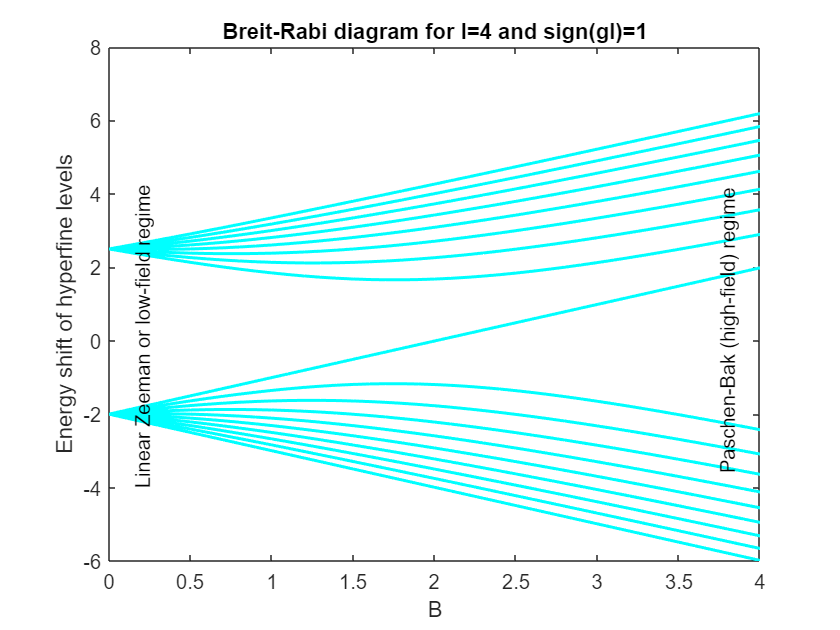

DeltaE_hf=A_hf*(I+1/2); 
B=0:0.1:4;
for mF=-I+1/2:I-1/2
    for s=[-1,1]
        plot(B, (-DeltaE_hf/(2*I+1)/2-gI*B*mF...
            +s*DeltaE_hf*sqrt(1+2*mF*(gI+gS)*B/(A_hf*(I+1/2)^2)...
            +(gI+gS)^2*B.^2/(A_hf^2*(I+1/2)^2))/2), "Color","c")
        hold on
    end
end
plot(B, (A_hf*I/2+B*gI*muB*I-B*gS*muB/2),"Color","c")
hold on
plot(B,(A_hf*I/2-B*gI*muB*I+B*gS*muB/2),"Color","c")

xlabel('B')
ylabel('Energy shift of hyperfine levels')
title(sprintf('Breit-Rabi diagram for I=%s and sign(gI)=%g',strtrim(rats(I)),sign(gI)))
ht1=text(3.8,-3.6,"Paschen-Bak (high-field) regime");
ht2=text(0.2,-4.0,"Linear Zeeman or low-field regime");
ht1.Rotation=90;
ht1.FontSize=10;
ht2.Rotation=90;
ht2.FontSize=10;

Let's plot together numerical and analytial results.  

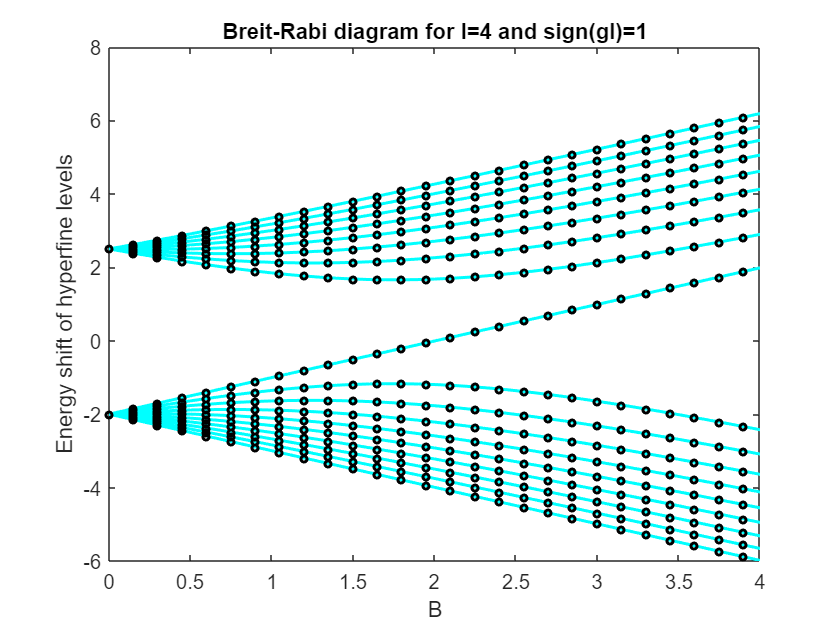

clf;

B=0:0.1:4;
for mF=-I+1/2:I-1/2
    for s=[-1,1]
        plot(B,(-DeltaE_hf/(2*I+1)/2-gI*B*mF...
            +s*DeltaE_hf*sqrt(1+2*mF*(gI+gS)*B/(A_hf*(I+1/2)^2)...
            +(gI+gS)^2*B.^2/(A_hf^2*(I+1/2)^2))/2), "Color","c")
        hold on
    end
end
plot(B, A_hf*I/2+B*gI*muB*I-B*gS*muB/2,"Color","c")
plot(B,A_hf*I/2-B*gI*muB*I+B*gS*muB/2,"Color","c")
for B=0:0.15:4
     plot(B,eig(H_hfB(B)),'ko',"MarkerSize",3)
     hold on
end
 xlabel('B')
 ylabel('Energy shift of hyperfine levels')
 title(sprintf('Breit-Rabi diagram for I=%s and sign(gI)=%g',strtrim(rats(I)),sign(gI)))
hold off;

Perfect comparison between analytical result and numerical simulation increases our confidence in our calculations. 

In weak magnetic field regime, where hyperfine interaction energy is much larger than energy associated with Zeeman coupling (linear Zeeman regime) relevant quantm numbers are $m_F$ and $F$.  Although $F$ is not a good quantum number for non-zero $B$,  in linear Zeeman regime admixture between states with different $F$ is small.

In strong magnetic field limit (Paschen-Back regime) hyperfine coupling is sub-leading only compared to magnetic field induced shifts of energy levels. One can observe that there are two sets of energy levels corresponding to electron spin parallel (high-field seeking spin states, higher energy states) or antiparrallel (low-field seeking spin states, lower-energy states) to external field and they are split by values of $m_F=m_S+m_I$, due to the subleading hyperfine coupling. Thus, there is a pair of $2I+1$ almost equidistant energy levels for strong magnetic fields - this is a so called hyperfine Paschen-Back regime. Relevant quantum numbers are $m_S$ and $m_F$. Although $m_S$ is not a good quantum number, in Paschen-Bak  regime admixture between states with different $m_S$ is small.

## Magnetic field dependence of ground states of $^6$Li and $^{87}$Rb

Below we will put true values of parameters and obtain Breit-Rabi diagram corresponding to the ground states of lithium 6 ($2 \,\,^2S_{1/2}$) and rubidium 87 ($5\,\, ^2S_{1/2}$) .

First we will put parameters corresponding to fermionic isotope of lithium, $^6$Li. True (experimentally determined) values of $A_{hf}$ and $g_I$ for alkali atoms can be found  in [2]. For $^6$Li: $I=1$, $A_{hf}$=152.1368407 MHz (to convert a value from megahertz to Joule we have to multiply it by one million times Planck's constant, $1J=1MHz 10^6h $ ) and $g_I=-0.0004476540$. 

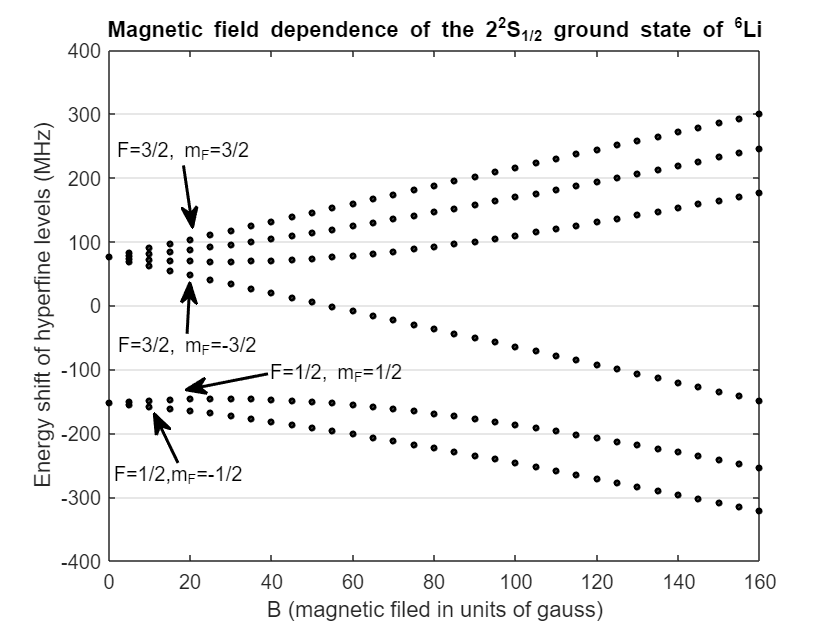

I=1; 
Ix=spin(I,'x');
Iy=spin(I,'y');
Iz=spin(I,'z');
muB=9.27401*1e-24;      % J/T, joule/tesla 
gI=-0.0004477;          % dimensionless number
gS=2.0023010;           % dimensionless number
h=6.62607*1e-34;        % J*s, value of Plank's constant in SI units
A_hf=152.1368407*1e6*h; % J
H_hfB=@(B) (A_hf*(kron(Sx,Ix)+kron(Sy,Iy)+kron(Sz,Iz))-gI*muB*B*kron(eye(2*S+1),Iz)...
          +gS*muB*B*kron(Sz,eye(2*I+1)));  
clf; 

for B=0:0.0005:0.016
     plot(B*1e4,eig(H_hfB(B))/(1e6*h),'ko',"MarkerSize",2) 
     % magnetic field is rescaled from tesla to gauss by 1T=10,000G
     % energy eigenvalues are rescaled by one million times Planck's
     % constant to present them in MHz, as usually done 
     hold on
end
hold off
xlabel('B (magnetic filed in units of gauss)')
ylabel('Energy shift of hyperfine levels (MHz)')
title(sprintf('Magnetic field dependence of the 2^2S_{1/2} ground state of ^6Li'))
set(gca,'XGrid','off','YGrid','on')
annotation('textarrow',[0.2227 0.226],[0.4702 0.551],'String','F=3/2, m_F=-3/2')
annotation('textarrow',[0.2184 0.2292],[0.7375 0.6394],'String','F=3/2, m_F=3/2')
annotation('textarrow',[0.319 0.2216],[0.4067 0.3812],'String','F=1/2, m_F=1/2')
annotation('textarrow',[0.2119 0.1837],[0.2652 0.3431],'String','F=1/2,m_F=-1/2')

Finally we plot Breit-rabi diagram for ground state of rubbidium 87 ($^{87}$Rb)  with $I=3/2$ and $g_I=-0.000995$.

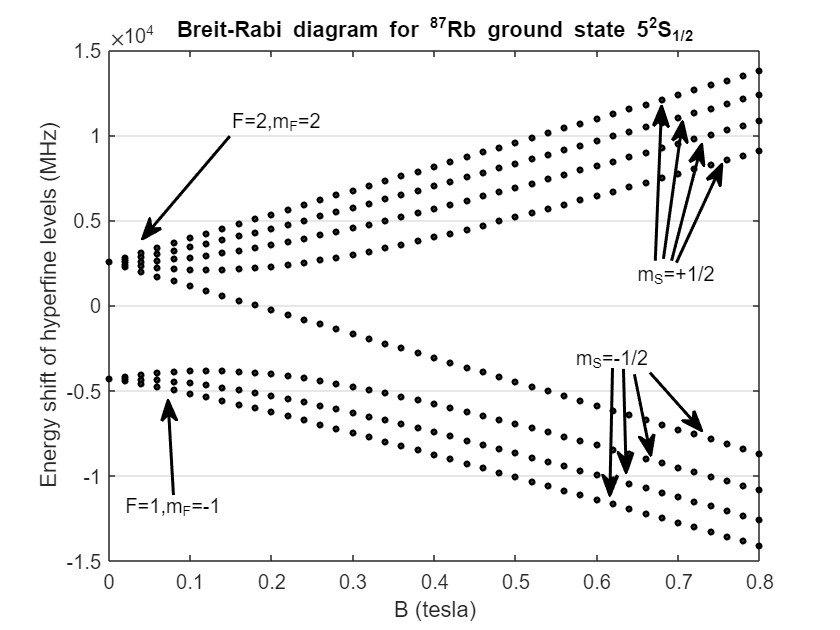

I=3/2; 
Ix=spin(I,'x');
Iy=spin(I,'y');
Iz=spin(I,'z');
A_hf=3417.34*1e6*h; % J (A_hf is multiplied by one million times Planck's constant 
                    % for converting from MHz to Joule).
gI=-0.000995;
H_hfB=@(B) (A_hf*(kron(Sx,Ix)+kron(Sy,Iy)+kron(Sz,Iz))-gI*muB*B*kron(eye(2*S+1),Iz)...
          +gS*muB*B*kron(Sz,eye(2*I+1))); 
                     
 % We can neglect the Zeeman coupling of the magnetic field with the
 % nuclear spin (since it is sub-leading), and check that 
 % splitting of energy levels in high-field (Paschen-Bak) regime is not due
 % to this coupling, but due to hyperfine coupling. Uncomment the following
 % hamiltonian and compare to previous result, you will hardly notice any difference
 % H_hfB=@(B) (A_hf*(kron(Sx,Ix)+kron(Sy,Iy)+kron(Sz,Iz))+gS*muB*B*kron(Sz,eye(2*I+1)));  
clf;
for B=0:0.02:0.8
     plot(B,eig(H_hfB(B))/(1e6*h),'ko',"MarkerSize",2) 
     % Energy is rescaled by one million times Planck's constant to convert it to MHz 
     hold on
end

 xlabel('B (tesla)')
 ylabel('Energy shift of hyperfine levels (MHz)')
 title(sprintf('Breit-Rabi diagram for ^{87}Rb ground state 5^2S_{1/2}'))
 set(gca,'XGrid','off','YGrid','on')
 hold off;
annotation('arrow',[0.7292 0.726],[0.4159 0.2139])
annotation('arrow',[0.7422 0.7454],[0.4145 0.25])
annotation('arrow',[0.7552 0.7747],[0.4061 0.2774])
annotation('arrow',[0.7801 0.7876],[0.5862 0.8315])
annotation('arrow',[0.7898 0.8125],[0.5891 0.807])
annotation('arrow',[0.7995 0.8353],[0.5862 0.7709])
annotation('textarrow',[0.7736 0.8353],[0.4087 0.3164],'String','m_S=-1/2')
annotation('textarrow',[0.8052 0.8593],[0.583 0.7388],'String','m_S=+1/2')
annotation('textarrow',[0.2736 0.1697],[0.7839 0.6209],'String','F=2,m_F=2')
annotation('textarrow',[0.2065 0.2],[0.2142 0.3643],'String','F=1,m_F=-1')

## **References**

[1]  E. Fermi, Z. Phys. **60**, 320 (1930); S. M. Blinder, Adv. Quantum Chem. **2**, 47 (1965). 

[2]  E. Arimondo, M. Inguscio, and P. Violino, Rev. Mod. Phys., **49**, 31 (1977).

function m=spin(S,component)
% this function outputs x, y, z components of spin-S vector operator 
    arguments
        S (1,1) double {mustBePhysical}   % mustBePhysical is a constraint on S defined below
        component char {mustBeMember(component,{'x','X', 'y','Y','z','Z'})} ='z'    
        % component is an optional argument, with a default value 'z'
    end        
    
    k=1:2*S; % don't use loops such as >>for k=1:S v(k)=sqrt(k*(2*S+1-k)); end
    v=sqrt(k.*(2*S+1-k));    % assignment v(k)=... would not be vectorized           
    
    S_minus=diag(v,-1);      % matrix corresponding to spin lowering ladder operator 
    S_plus=S_minus';         % matrix corresponding to spin raising ladder operator 
    % S_plus=diag(v,1);      % put vector v on the upper diagonal of a matrix
    switch component
        case {'x','X'}
            m=(S_plus+S_minus)/2;
        case {'y','Y'}
            m=(S_plus-S_minus)/2i;
        case {'z','Z'}               
            m=diag(S:-1:-S); % Sz=[S_plus,S_minus]/2 
    end
end


function mustBePhysical(S)
    if  mod(2*S,1) || S<0
        eidType = 'myComponent:inputError';
        msgtext = 'Spin value must be non-negative integer or half-integer number';
        throw(MException(eidType,msgtext))
    end
end 